# LAB 3 

## 1)

### A)

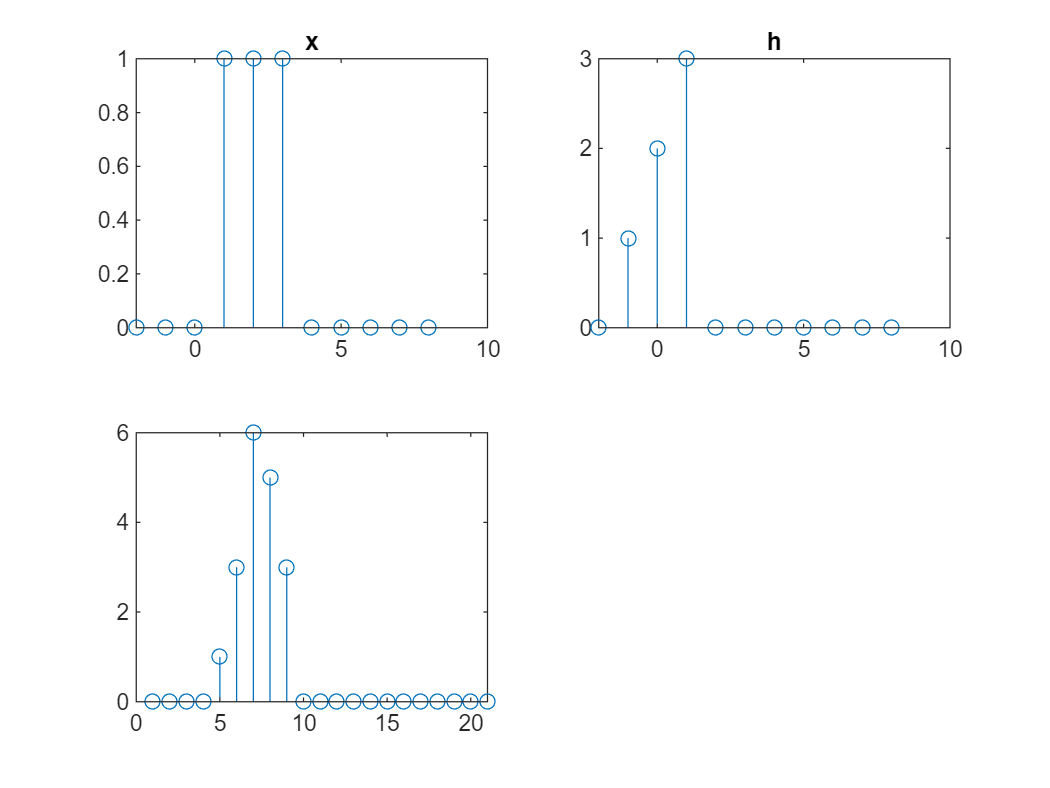


x=ones(1,11);
x(7:end)=0;
x(1,1:3)=0;
t=-2:1:8;
y=zeros(1,11);
y(1,2)=1;y(1,3)=2;y(1,4)=3;
figure(1)
subplot(2,2,1)
stem(t,x)
title('x');
subplot(2,2,2)
stem(t,y)
title('h');
z=conv(x,y);
subplot(2,2,3);
stem(z);

## B)

% z2=zeros(1,21);
% for i=1:11
%     for k=1:11
%       
%     z3=x(1,i).*y(1,k);
%     z2(1,k)=z2(1,k)+z3;
%     subplot(2,2,4);
%     drawnow;
%     stem(z2);hold on;
%     stem(x);
%     stem(y(1,k));
%     end
% end
% 


## C)

disp(size(x));

     1    11



[m,n]=size(x);
disp(size(y));

     1    11



h=zeros(n,n);
for i=1:n
    h(i,:)=y(1,i);
end

disp(size(h));

    11    11



nice=(h*x')';
disp(size(nice));

     1    11



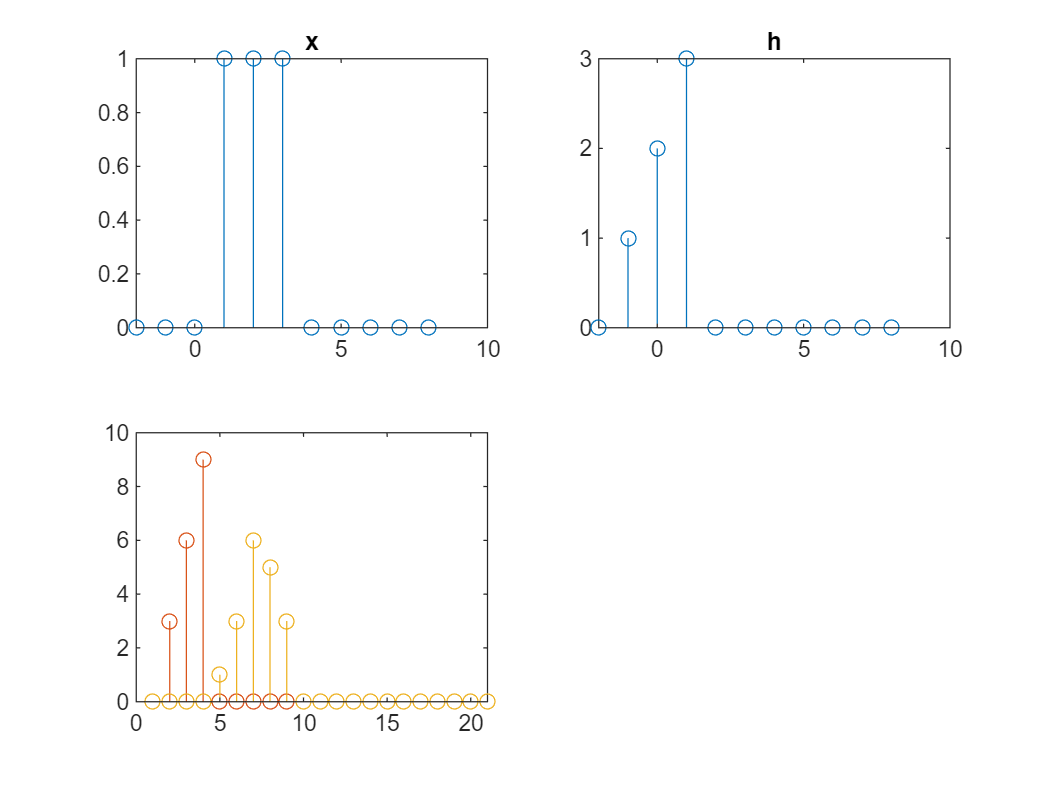

stem(nice);
hold on;
stem(conv(x,y));